# Gridded NORA3 data (subset): Getting a time series from an offshore location

The third example introduces an alternative way to extract hourly data in terms of time series, from one location using the NORA3 subset [1], which is faster to download but does not contain the temperature data on pressure levels.

References

[1] [https://thredds.met.no/thredds/projects/nora3_subsets.html](https://thredds.met.no/thredds/projects/nora3_subsets.html) 

## Definition of the parameters

Some days in April 2016 in the North Sea

clearvars;close all;clc;
targetDate = datetime(2016,04,10):days(1):datetime(2016,04,12);
resolution = 0.025; % resolution for latitude and longitude in degrees (< 3 km)
targetLat = [54.014861]; % target latitude
targetLon = [6.587639];  % target longitude
N = numel(targetDate);
Nz = 7; % heights levels

Nlat = numel(targetLat);
Nlon = numel(targetLon);
U = NaN(N*24, Nlat, Nlon, Nz); % Mean wind speed profile
D = NaN(N*24, Nlat, Nlon, Nz); % Mean wind direction profile
P0 = NaN(N*24, Nlat, Nlon); % Surface air pressure
RH0 = NaN(N*24, Nlat, Nlon); % Relative humidity
rain = NaN(N*24, Nlat, Nlon); % Precipitation
T0 = NaN(N*24, Nlat, Nlon); % Surface temperature
time = NaT(1, N*24);

for ii = 1:N
    targetYear = num2str(year(targetDate(ii)));
    targetMonth = num2str(month(targetDate(ii)));
    targetDay = num2str(day(targetDate(ii)));
    tic
    [mydata] = getNORA3_subset(targetLat, targetLon, targetYear, ...
        targetMonth, targetDay, resolution, 'optPara', 'atm_1h');
    toc
  
    startIndex = (ii-1) * 24 + 1;
    endIndex = ii * 24;
    
    P0(startIndex:endIndex, :, :) = squeeze(mydata.P0);
    T0(startIndex:endIndex, :, :) = squeeze(mydata.T0);
    RH0(startIndex:endIndex, :, :) = squeeze(mydata.RH0);
    rain(startIndex:endIndex, :, :) = squeeze(mydata.precipitation);
    U(startIndex:endIndex, :, :, :) = squeeze(mydata.U)';
    D(startIndex:endIndex, :, :, :) = squeeze(mydata.D)';
    time(startIndex:endIndex) = mydata.time;
end

Elapsed time is 2.967130 seconds.
Elapsed time is 2.636287 seconds.
Elapsed time is 3.387937 seconds.



z = mydata.z;

## Visualisation of the results

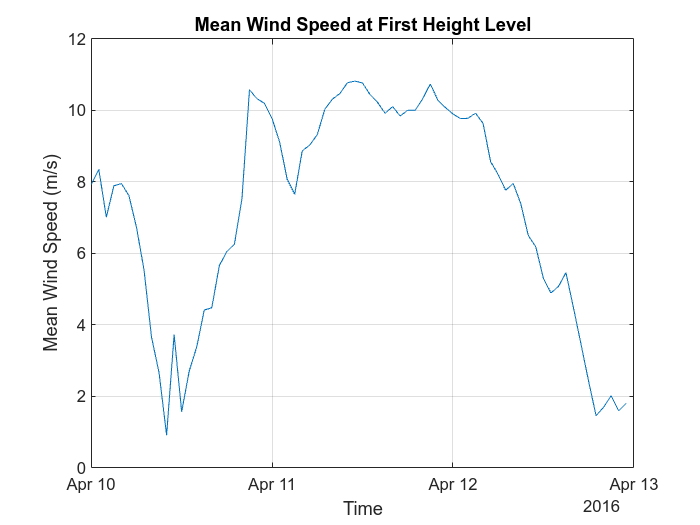

%% Plot Mean Wind Speed at the first height level
figure;
plot(time, squeeze(U(:,1,1,1)));  % Assuming Nlat = 1 and Nlon = 1 for simplicity
title('Mean Wind Speed at First Height Level');
xlabel('Time');
ylabel('Mean Wind Speed (m/s)');
grid on;

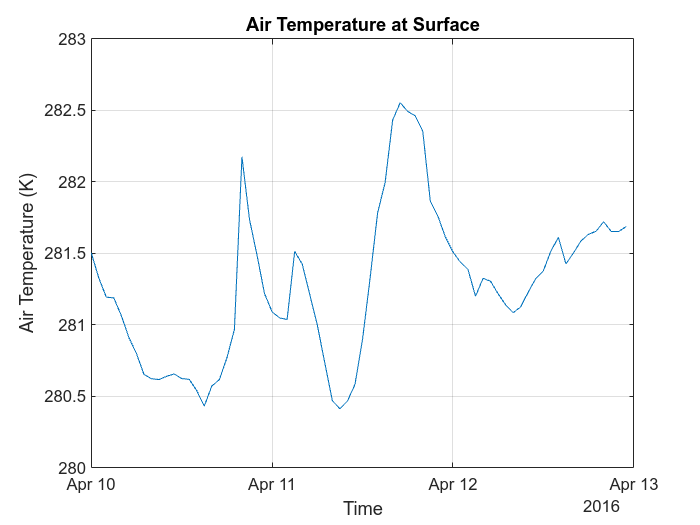


%% Plot Air Temperature at the surface
figure;
plot(time, squeeze(T0(:,1,1)));
title('Air Temperature at Surface');
xlabel('Time');
ylabel('Air Temperature (K)');
grid on;

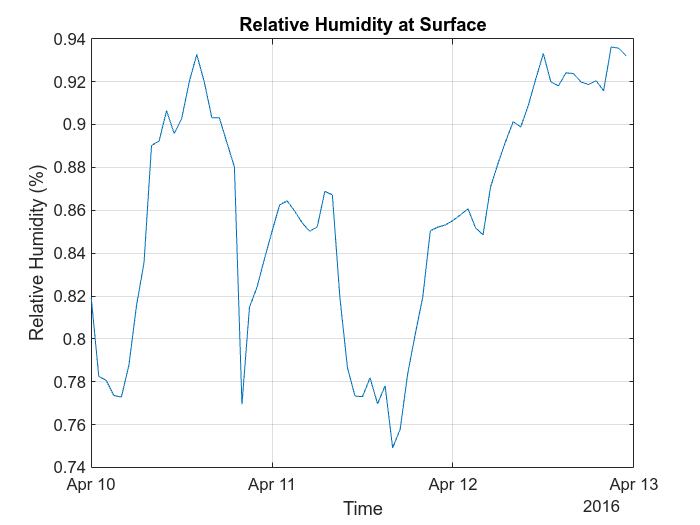


%% Plot Relative Humidity at the surface
figure;
plot(time, squeeze(RH0(:,1,1)));
title('Relative Humidity at Surface');
xlabel('Time');
ylabel('Relative Humidity (%)');
grid on;

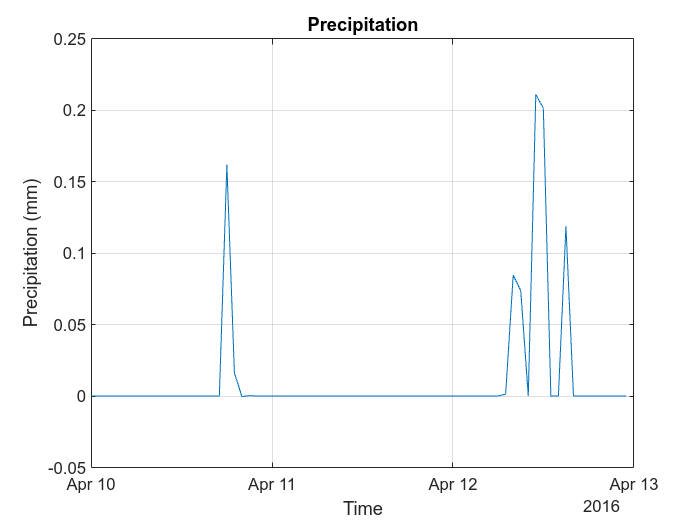


%% Plot Precipitation
figure;
plot(time, squeeze(rain(:,1,1)));
title('Precipitation');
xlabel('Time');
ylabel('Precipitation (mm)');
grid on;

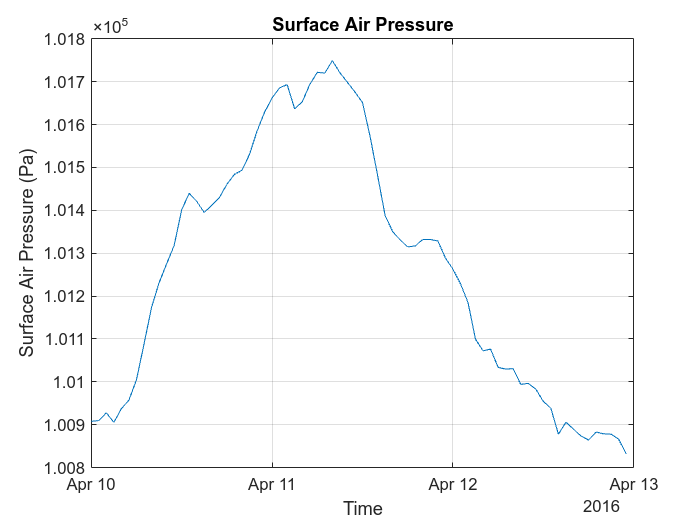


%% Plot Surface Air Pressure
figure;
plot(time, squeeze(P0(:,1,1)));
title('Surface Air Pressure');
xlabel('Time');
ylabel('Surface Air Pressure (Pa)');
grid on;

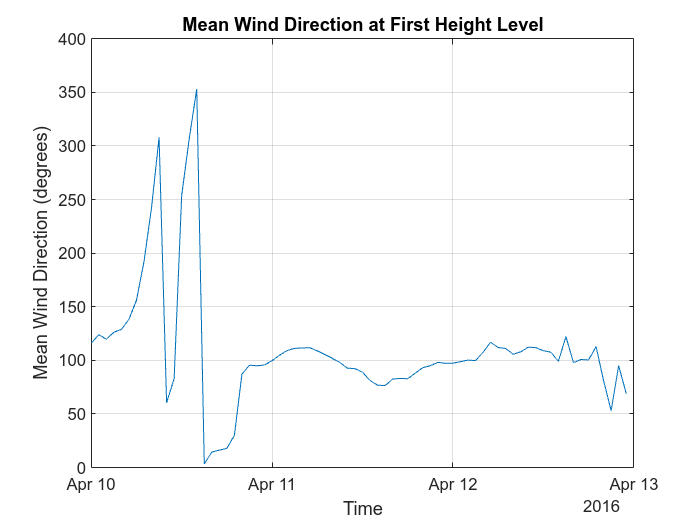


%% Plot Mean Wind Direction at the first height level
figure;
plot(time, squeeze(D(:,1,1,1)));  % Again, assuming Nlat = 1 and Nlon = 1
title('Mean Wind Direction at First Height Level');
xlabel('Time');
ylabel('Mean Wind Direction (degrees)');
grid on;



figure
indN = 19:2:32;
COLOR = parula(numel(indN));
clear leg pl
ll=1;
for ii=indN
    
    % Interpolate the profiles
    oldZ = mydata.z;
    oldU = squeeze(U(ii,:,:,:)); % old wind speed profile from the NORA3 database
    newZ = logspace(log10(oldZ(1)),log10(oldZ(end)),100); % new hright vector with logarithmic spacing
    [z0] = getz0_charnock(oldU(1),oldZ(1),0.016); % Get the roughness of the sea by solving Charnock's equation
    u_star = oldU(1)*0.4./log(oldZ(1)./z0);  % frictionv velocity estimated with the logarithmic mean wind speed profile
    [newU,rmse] = interpU(oldZ,z0,oldU,newZ,u_star);
    
    
    pl(ll) = plot(newU,newZ,'color',COLOR(ll,:));
    hold on
    box on
    grid on
    plot(oldU,oldZ,'o','color',COLOR(ll,:));
    leg{ll} = datestr(time(ii));
    ll=ll+1;
end

Charnock relationship leads to zsea = 7.1e-05 m 
Charnock relationship leads to zsea = 1.2e-04 m 
Charnock relationship leads to zsea = 2.6e-04 m 
Charnock relationship leads to zsea = 2.3e-04 m 
Charnock relationship leads to zsea = 1.4e-04 m 
Charnock relationship leads to zsea = 1.8e-04 m 
Charnock relationship leads to zsea = 2.0e-04 m 


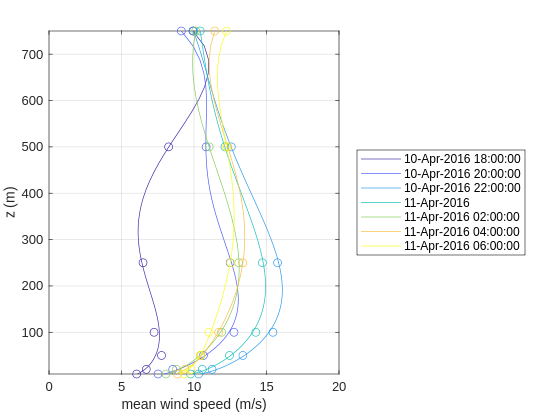

ylabel('z (m)')
xlabel('mean wind speed (m/s)')
axis tight
xlim([0 20])
legend(pl,leg{:},'location','eastoutside')